# Taller 11

### Modelo epidemiológico SIRV.

### Juan Camilo Ospino M.

## Introducción

En el mundo real, existen problemas que requieren soluciones con un enfoque multidisciplinario. A través de las ecuaciones diferenciales, es posible caracterizar y encontrar diferentes soluciones para problemas a lo largo del tiempo, como un estudio epidemiológico. Las ecuaciones diferenciales por ende pueden brindar información crucial para el manejo de una posible epidemia. En este taller se procura resolver un estudio epidemiológico SIRV, relacionando sus variables de estado a lo largo del tiempo.

## Materiales y métodos

El modelo a utilizar, conocido como modelo SIRV, procura analizar el comportamiento de un patógeno a través de ecuaciones diferenciales no lineales para encontrar su comportamiento transitorio. El modelo consta de las siguientes variables de estado:

- S: Suceptibilidad en la población de estudio.

- I: Infectados presentes en la población de estudio.

- R: Recuperados presentes en la población de estudio.

- V: Vacunados presentes en la población de estudio.

Para este modelo, se realizan las siguientes suposiciones:

- La población es invariante en el tiempo, por lo que no se consideran natalidades ni fatalidades. La población en el estudio, al sumar S, I, R y V debe dar 1 y se conoce como **N.**

                
$$N=S\left(t\right)+I\left(t\right)+T\left(t\right)+V\left(t\right)$$


- La enfermedad se transmite por contacto directo y se mantiene la tasa de infección es proporcional a la multiplicación de los infectados y los susceptibles. $I\left(t\right)*S\left(t\right)$

El modelo a emplear procura encontrar la tasa de transmisión ($\beta$), de recuperación ($\gamma$), de vacunación ($\delta$) a través de las siguientes ecuaciones:


$$S^{\prime } =-\delta *S\left(t\right)*I\left(t\right)-\delta *S\left(t\right)$$



$$I^{\prime } =\delta *S\left(t\right)*I\left(t\right)-\gamma *I\left(t\right)$$



$$R^{\prime } =\gamma *I\left(t\right)$$



$$V^{\prime } =\delta *S\left(t\right)$$


## Resultados y Análisis

## 1

Con los valores para beta, gamma y delta iniciales provistos por el taller, se procede a realizar el cálculo de cada variable de estado a lo largo del tiempo.

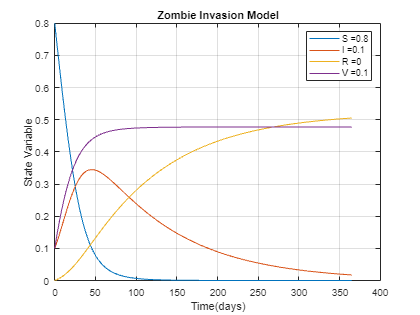

%INIT symbolic
syms S(t) I(t) R(t) V(t);


%INIT Constants
beta = 0.1; %Transmission
gamma = 0.01; % Vaccination
delta = 0.02; %Recovered

%INIT State derivatives

dSZ = diff(S(t), t, 1); %Succeptible
dIZ = diff(I(t), t, 1); %Infected
dRZ = diff(R(t), t, 1); %Recovered
dVZ = diff(V(t), t, 1); %Vaccinated

%INIT initial conditions. Must add up to 100

ic_SZ =  0.8;
ic_IZ =  0.1;
ic_RZ =  0;
ic_VZ =  0.1;

ic_Vector = [ic_SZ ic_IZ ic_RZ ic_VZ]; %Since ODE45, must be a vector to pass as parameter

%INIT State equations

Rate_SZ = -beta * S * I - delta * S;
Rate_IZ = beta * I * S - gamma * I;
Rate_RZ = gamma * I;
Rate_VZ = delta * S;

%INIT time parameter

ts = 1; %timespan (1 day).
tmin = 0; %Start as day zero.
tmax = 365; %Finish as one year.
tspan = tmin:ts:tmax; %To pass as argument, it must be a range object

%Solve using ODE45

state_function = odeFunction([Rate_SZ Rate_IZ Rate_RZ Rate_VZ], [S I R V]); %State Equations and State Variables into function
[Time, Output] = ode45(state_function, tspan, ic_Vector);

%Plotting

figure;
plot(Time, Output);
grid on;
hold on;
xlabel('Time(days)');
ylabel('State Variables');
title('Zombie Invasion Model');
legend({strcat('S =  ', num2str(ic_SZ)), strcat('I = ', num2str(ic_IZ)), strcat("R =", num2str(ic_RZ)), strcat("V =", num2str(ic_VZ))});

Con los valores iniciales de 0.8, 0.1, 0 y 0.1 para S, I, R, V respectivamente, se observa el comportamiento del sistema inicialmente en un periodo de 365 días. Se observa que el número de susceptibles decrece cuando el número de recuperados y vacunados alcanza su máximo y se estabiliza. El número de infectados tiende a cero con el paso del tiempo y posee un comportamiento inverso al de los vacunados y recuperados.

## 1.1

A continuación, se procede a analizar cómo influye el cambio en el número de vacunados en el modelo, sin alterar los valores de beta, delta y gamma.

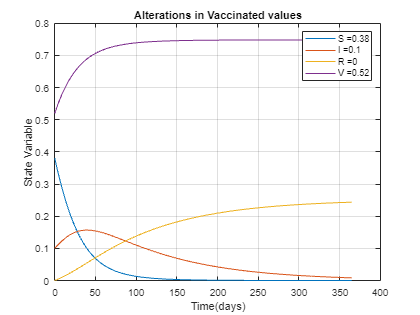

clf

%Alter V(t) initial condition and obtain time/value vectors
v_val = 0.52;
IC_Vacc = [0.9-v_val 0.1 0 v_val];
[Time2, Output2] = ode45(state_function, tspan, IC_Vacc);

%Plot
figure;
plot(Time2, Output2);
grid on;
hold on;
xlabel('Time(days)');
ylabel('State Variable');
title('Alterations in Vaccinated values');
legend({strcat('S =  ', num2str(IC_Vacc(1))), strcat('I = ', num2str(IC_Vacc(2))), strcat("R =", num2str(IC_Vacc(3))), strcat("V =", num2str(IC_Vacc(4)))});

Al comparar la primera y segunda gráfica, se logró identificar el efecto de la vacunación en la población susceptible. Por ende, se entiende que al incrementar la población vacunada al rededor del 50%, el número de infectados pasa a estar aproximadamente al 15%.

## 2

Adicionalmente, se busca analizar el impacto del número inicial los individuos infectados en cada grupo a lo largo del tiempo. Para lo anterior, se emplearán 5 valores de I en las condiciones iniciales. Nuevamente, la suma de dicha población deberá ser igual a 1 para cumplir con los supuestos del modelo.

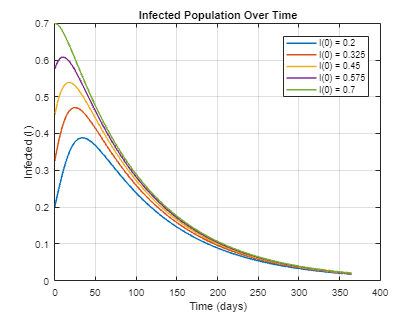

ic_IZ_values = linspace(0.2, 0.7, 5); % INIT Values of I using linspace

% Initialize array to store results of I
Results = cell(1, length(ic_IZ_values));

% Create figure
figure;

for i = 1:length(ic_IZ_values)
    %  Condition = S + I + R + V = 1
    ic_SZ = 0.8 - ic_IZ_values(i);
    ic_RZ = 0;
    ic_VZ = 0.1;
    ic_Vector = [ic_SZ ic_IZ_values(i) ic_RZ ic_VZ];

    % Solve using ODE45
    [Time, Output] = ode45(state_function, tspan, ic_Vector);

    %Store results in array
    Results{i} = Output;

    % Plotting I
    plot(Time, Output(:, 2), 'LineWidth', 1.5); 
    hold on;
end

% Plotting methods
grid on;
xlabel('Time (days)');
ylabel('Infected (I)');
title('Infected Population Over Time');
legend_str = cellfun(@(x) ['I(0) = ' num2str(x)], num2cell(ic_IZ_values), 'UniformOutput', false); %Extract values from array and then put into legend
legend(legend_str, 'Location', 'Best');

Partiendo de la condición inicial en donde la suma de los grupos poblacionales siempre es igual a 1, al cambiar un valor en el número de infectados, el número de otros grupos poblacionales, como el de los susceptibles, varió, mientras que el número de vacunados se mantuvo a lo largo del tiempo. En la gráfica se observa que del valor inicial de Infectados, el comportamiento tiende a decrecer puesto que los susceptibles empieza a decrecer, eventualmente tendiendo a cero al final del estudio.

## 3

Para el siguiente caso, el número de individuos en los grupos poblacionales se mantiene, procurando definir el comportamiento de la tasa de transmisión $\beta$ en el grupo de los Infectados.

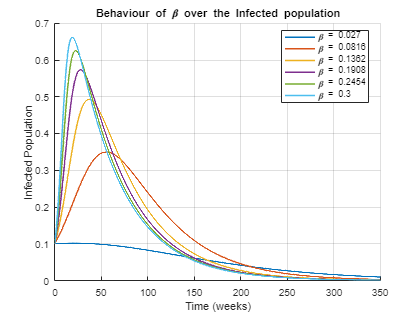

syms s(t) i(t) r(t) v(t)

% INIT Values
beta_values = linspace(0.027, 0.3, 6); % Generate 6 beta values
gamma = 0.02; 
delta = 0.001;

% ODE
f3 = gamma * i;
f4 = delta * s;

% Time constraints
h = 0.1;
tmin = 0;
tmax = 350;
tspan = tmin:h:tmax;

% Initial conditions Vector
ci = [0.8 0.1 0 0.1];

% Figure and numerical solution
figure;
hold on;

for k = 1:length(beta_values)
    f1 = -beta_values(k) * s * i - delta * s;
    f2 = beta_values(k) * s * i - gamma * i;
    f = odeFunction([f1 f2 f3 f4],[s i r v]); 
    [t, x] = ode45(f, tspan, ci);
    
    plot(t, x(:, 2), 'LineWidth', 1.5);
end

%Plot Methods
xlabel('Time (weeks)');
ylabel('Infected Population');
title('Behaviour of \beta over the Infected population');
grid on;
legend(cellfun(@(x) ['\beta = ' num2str(x)], num2cell(beta_values), 'UniformOutput', false), 'Location', 'Best'); %Depict values of beta for each plot at legend

La tasa de transmisibilidad $\beta$ es la capacidad de un patógeno para lograr reproducibilidad en la población.Se encuentra que al disminuir  el valor de $\beta$, el comportamiento de los infectados no incrementa rápidamente. La pendiente y el crecimiento del número de los infectados decrece cuando el valor disminuye, esto concuerda con el modelo matemático planteado para el cálculo de I en las ecuaciones diferenciales 

## 4

Para el caso a continuación, se estudia el cambio en la tasa de recuperación $\gamma$ y cómo esta afecta el número de individuos presentes en el grupo poblacional de los infectados.

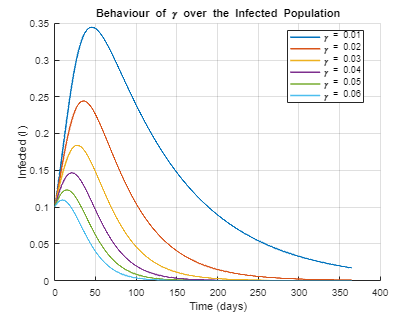

syms s(t) i(t) r(t) v(t)

%INIT Values
beta = 0.1; % Constant beta
gamma_values = linspace(0.01, 0.06, 6); % Linspace for gamma
delta = 0.02;

% Time Constraints
h = 0.1;
tmin = 0;
tmax = 365;
tspan = tmin:h:tmax;

% Initial condition Vector
ci = [0.8 0.1 0 0.1];

% INIT Result Array
Results = cell(1, length(gamma_values));

%INIT Figure and hold
figure;
hold on; 

for j = 1:length(gamma_values)
    gamma = gamma_values(j); %Update values of gamma
    
    % Initial conditions SIRV
    ic_SZ = 0.8;
    ic_IZ = 0.1;
    ic_RZ = 0;
    ic_VZ = 0.1;

    ic_Vector = [ic_SZ ic_IZ ic_RZ ic_VZ];
    
    % State Equations
    Rate_SZ = -beta * s * i - delta * s;
    Rate_IZ = beta * i * s - gamma * i;
    Rate_RZ = gamma * i;
    Rate_VZ = delta * s;

    % State function
    state_function = odeFunction([Rate_SZ Rate_IZ Rate_RZ Rate_VZ], [s i r v]);

    % Solve using IDE
    [Time, Output] = ode45(state_function, tspan, ic_Vector);

    % Store the results in Array
    Results{j} = Output;

    %Plot I
    plot(Time, Output(:, 2), 'LineWidth', 1.5);
end

% Plot Methods
grid on;
xlabel('Time (days)');
ylabel('Infected (I)');
title('Behaviour of \gamma over the Infected Population');
legend(cellfun(@(x) ['\gamma = ' num2str(x)], num2cell(gamma_values), 'UniformOutput', false), 'Location', 'Best'); %Depict values of gamma for each plot at legend

El comportamiento de la tasa de recuperación $\gamma$ es inverso al de la tasa de infección $\beta$. La curva de infección en la población disminuye en la medida que la tasa de recuperacion incrementa. En un caso más aproximado a la realidad, este es el parámetro al cual la mayor cantidad de esfuerzos deberían ser destinados, puesto que tiene una relación directa con el comportamiento de la enfermedad en la población. Se muestra en la gráfica que un cambio de 0.05 en el valor de $\gamma$supone una diferencia de 0.25 en el pico máximo del número de infectados.

## 5

Un parámetro contribuyente para el estudio de la población infectada es el de la tasa de vacunación $\delta$. A continuación se grafica el comportamiento de esta tasa en la población de los infectados.

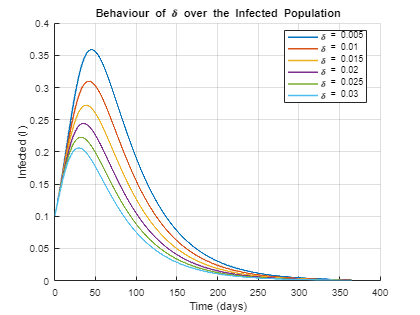

syms s(t) i(t) r(t) v(t)

% INIT Values
beta = 0.1;
gamma = 0.02;
delta_values = linspace(0.005, 0.03, 6); % Linspace for delta

% Time Constraints
h = 0.1;
tmin = 0;
tmax = 365;
tspan = tmin:h:tmax;

% Initial condition vector
ci = [0.8 0.1 0 0.1];

% INIT result array
Results = cell(1, length(delta_values));

% Create a new figure, hold on
figure;
hold on; 

for j = 1:length(delta_values)
    delta = delta_values(j); % Update delta
    
    % Reset Initial condition vector
    ic_SZ = 0.8;
    ic_IZ = 0.1;
    ic_RZ = 0;
    ic_VZ = 0.1;

    ic_Vector = [ic_SZ ic_IZ ic_RZ ic_VZ];
    
    % State Equations
    Rate_SZ = -beta * s * i - delta * s;
    Rate_IZ = beta * i * s - gamma * i;
    Rate_RZ = gamma * i;
    Rate_VZ = delta * s;

    % State function
    state_function = odeFunction([Rate_SZ Rate_IZ Rate_RZ Rate_VZ], [s i r v]);

    % Solve using ODE45
    [Time, Output] = ode45(state_function, tspan, ic_Vector);

    % Store results in array
    Results{j} = Output;

    % Plot I
    plot(Time, Output(:, 2), 'LineWidth', 1.5);
end

% Plot Methods
grid on;
xlabel('Time (days)');
ylabel('Infected (I)');
title('Behaviour of \delta over the Infected Population');

% Create a legend
legend(cellfun(@(x) ['\delta = ' num2str(x)], num2cell(delta_values), 'UniformOutput', false), 'Location', 'Best'); %Depict values of delta for each plot at legend

Al igual que la tasa de recuperación $\gamma$, la tasa de vacunación $\delta$ supone un efecto directo y visible sobre la cantidad de individuos infectados. Al incrementar $\delta$, el número máximo de infectados disminuye drásticamente. En una aplicación real, la inmunización de la población juega un papel importante en la dispersión de patógenos, es por esto que los planes de vacunación son la piedra angular de cualquier programa de salud preventivo. Se demostró con el comportamiento de la reciente pandemia del COVID-19, que al inmunizar la población, la carga a la infraestructura hospitalaria disminuyó. Este comportamiento responde al modelo matemático.

### Discusión

En esta práctica, se logró observar el comportamiento de un modelo epidemiológico basado en ecuaciones diferenciales y su característica dinámica. A través de la caracterización de los 4 grupos poblacionales (Susceptibles, Infectados, Recuperados y Vacunados), se logró modelar la propagación de un patógeno en un periodo de tiempo de 365 días. También se logró caracterizar el comportamiento de las diferentes tasas (infección, recuperación y vacunación) en la población crítica del estudio, la de los infectados. Aún cuando el modelo tiene suposiciones estáticas en donde la población es invariante, este permite un acercamiento al comportamiento real en una epidemia, permitiendo tomar decisiones sobre políticas importantes que puedan ayudar al manejo de un sistema de salud y sus miembros constituyentes.